# H2

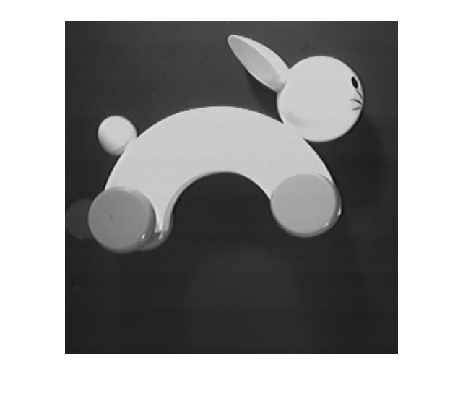

I = imread('rabbit.jpg');
imshow(I)

SL =     88    44    43    46    44    47    46    47    45    43    44    44    43    45    46    48    47    47    47    47    47    47    47    47    47    47    46    49    47    50    49    49    49    49    48    51    49    53    51    51    51    51    50    53    51    54    53    54    51    52
    44     0     1     1     1     1     0     1     0     1     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     0     0     0     1     2     0     2     2     0     0     0     1     1     1     1     0     1     1     0
    44     0     1     1     1     1     0     1     0     1     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     1     1     1     1     0     0     1     1     0     2     2     0     2     2     0     0     1     1     1     1     0     1     1     0
    44     0     1     1     1     1     0     1     0     1     0     0     1     0     0  

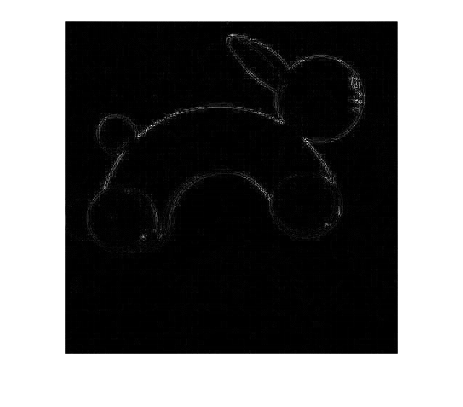

hL = [0 1 0; 1 -4 1; 0 1 0];
L = abs(imfilter(double(I), hL));

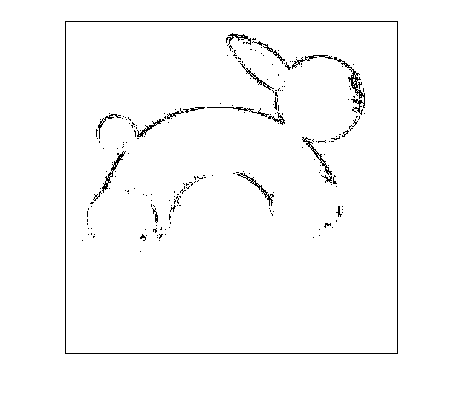

L = L > 20;
imshow(L,[])

hx = [1 0 -1; 2 0 -2; 1 0 -1];
hy = hx';
Gx = abs(imfilter(double(I), hx));
Gx = Gx/max(max(Gx));
Gy = abs(imfilter(double(I), hy));
Gy = Gy/max(max(Gy));
G = (Gx + Gy);
G = G > 0.3

G = 461×461 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

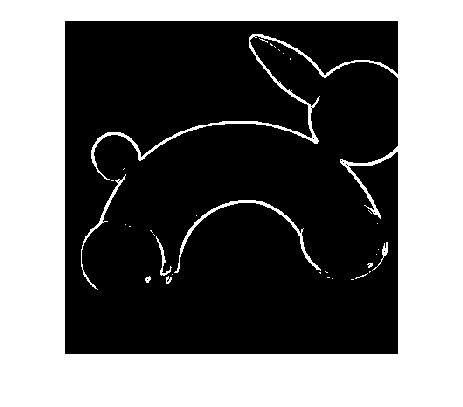

imshow(G,[])




% R = R/max(max(R)) < 0.6;
% imshow(R,[]);
% D = L - R;
% imshow(D);